clear;close all;clc;

Расмматриваемый сигнал опеределяется формулой:


$$E=A\cdot e^{j\cdot 2\pi \textrm{fx}\;\frac{\sin \left(\varphi \right)}{c}}$$


определённый на некотором множестве $\{x\}$

Здесь: $A$и$f$ – амплитуда и частота сигнала, $c$ – скорость света. Константы для данной системы. $\varphi$ – направление прихода сигнала. 

Идеальным случаем является выбор элементов $x_n = n \frac{\lambda}{2}$ , где $\lambda$ – длина волны сигнала

c = physconst("Lightspeed");
% freq params
f = 5e9; % 5 GHz
w = 2*pi*f;
lam = freq2wavelen(f);
k = 2*pi/lam;
% array params
xmtmin = -0;xmtmax = 30;
dOk = lam/2;
NOk = round((xmtmax-xmtmin)/dOk);
dxOk = dOk*(xmtmin:1:xmtmax)';
aimAngles = [56.5];
aimAmps   = [0]; %dB

Рассмотрим значение фазы от элемента к элементу:

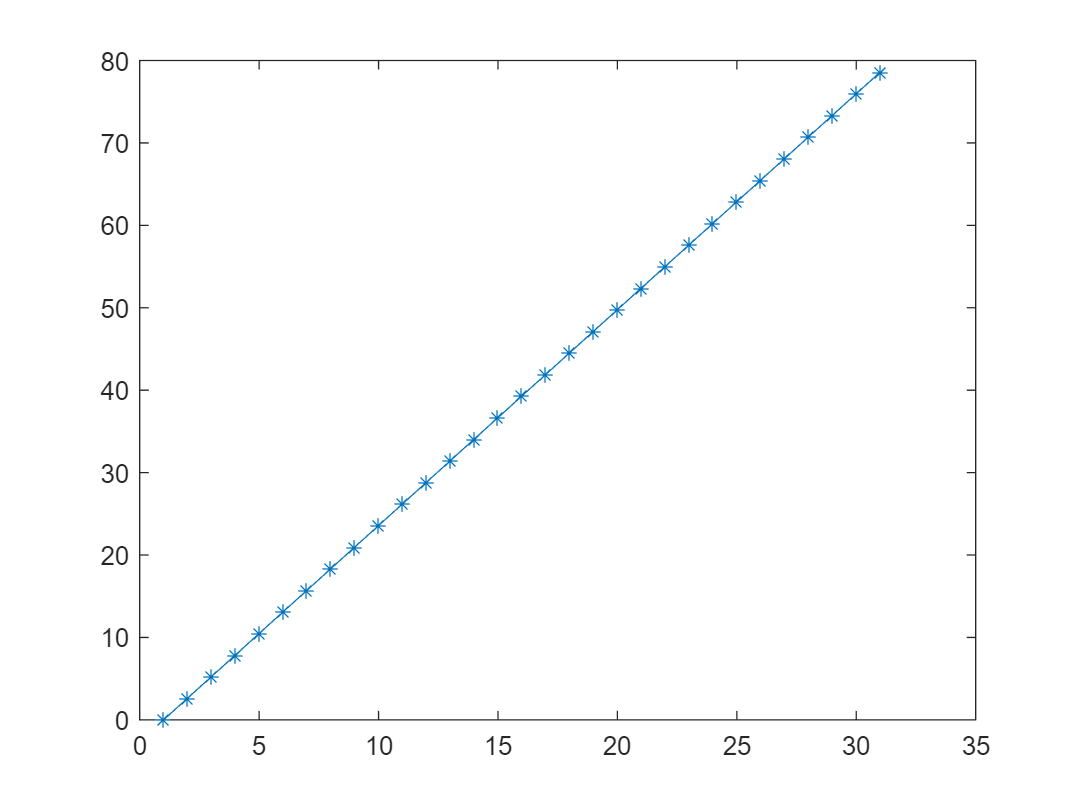

[valuesOk, phasesOk] = distribution_former(dxOk,f,aimAngles, aimAmps);
plot(phasesOk,'-*')

Однако с датчиков будут получены значения от $-\pi$ до $\pi$

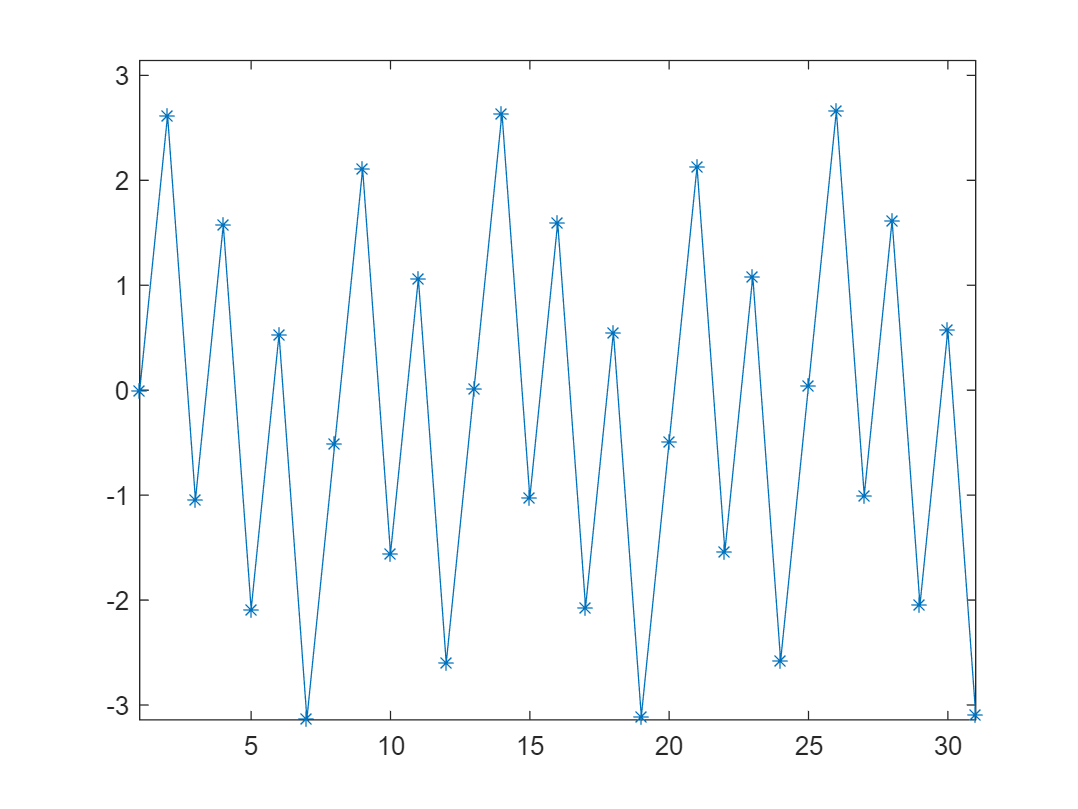

plot(angle(valuesOk),'-*'); axis([-inf inf -pi pi])

Но изменение значения от элемента к элементу постоянное:

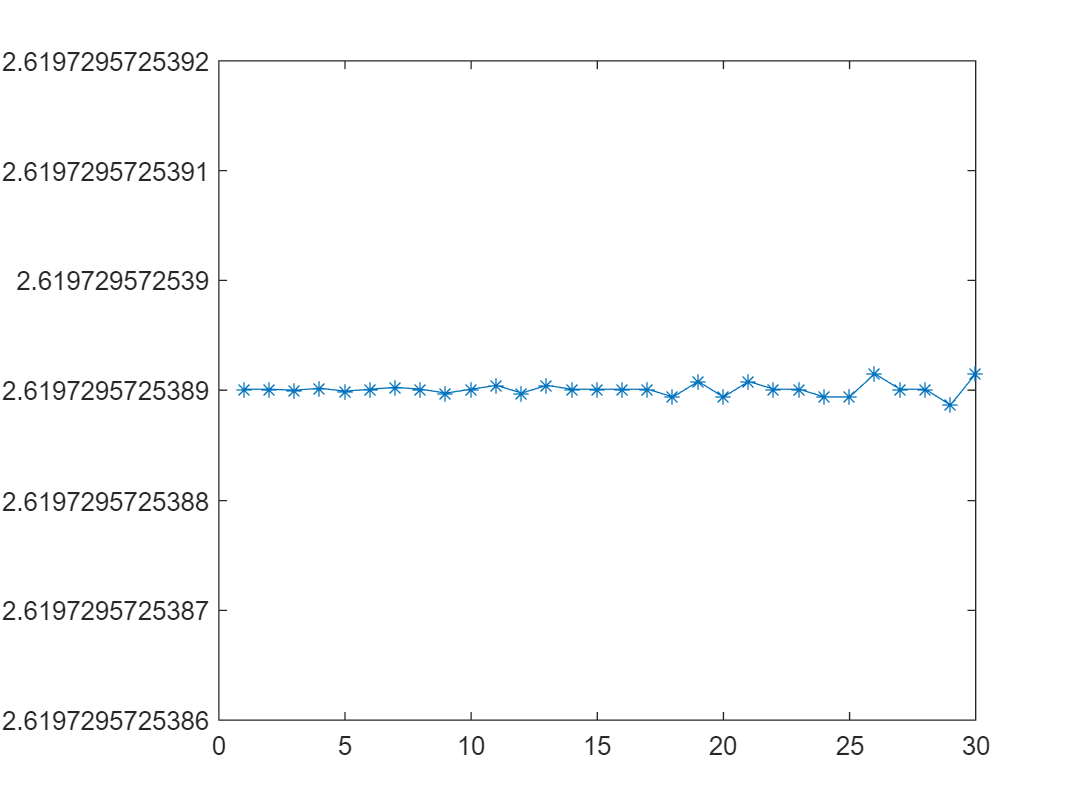

plot(diff(phasesOk),'-*');

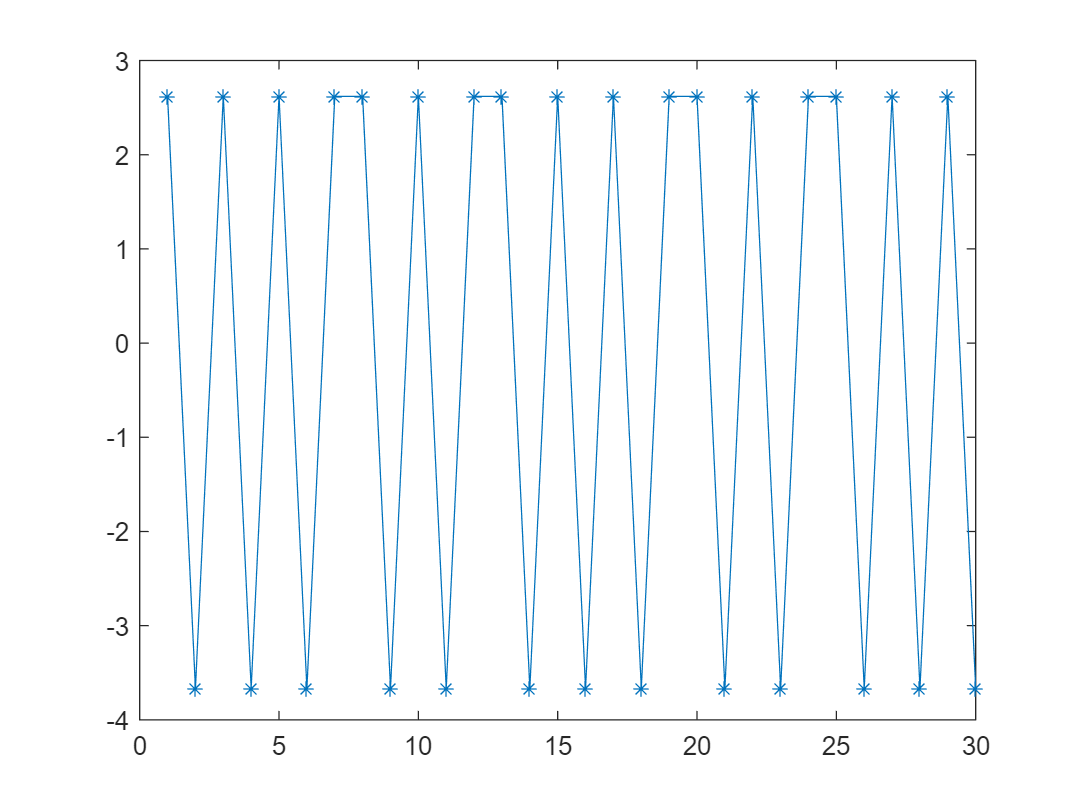

plot(diff(angle(valuesOk)),'-*');

А действительная и мнимая часть сигнала будут следующими (косинус и синус соответственно):

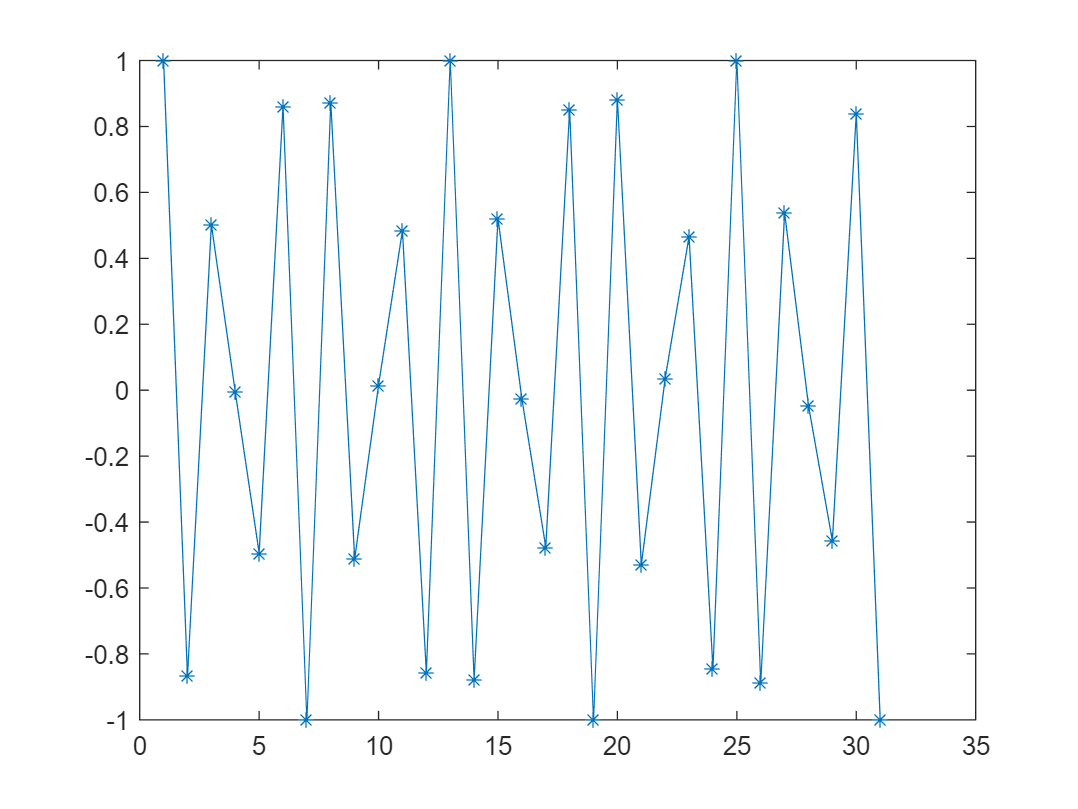

plot(real(valuesOk),'-*');

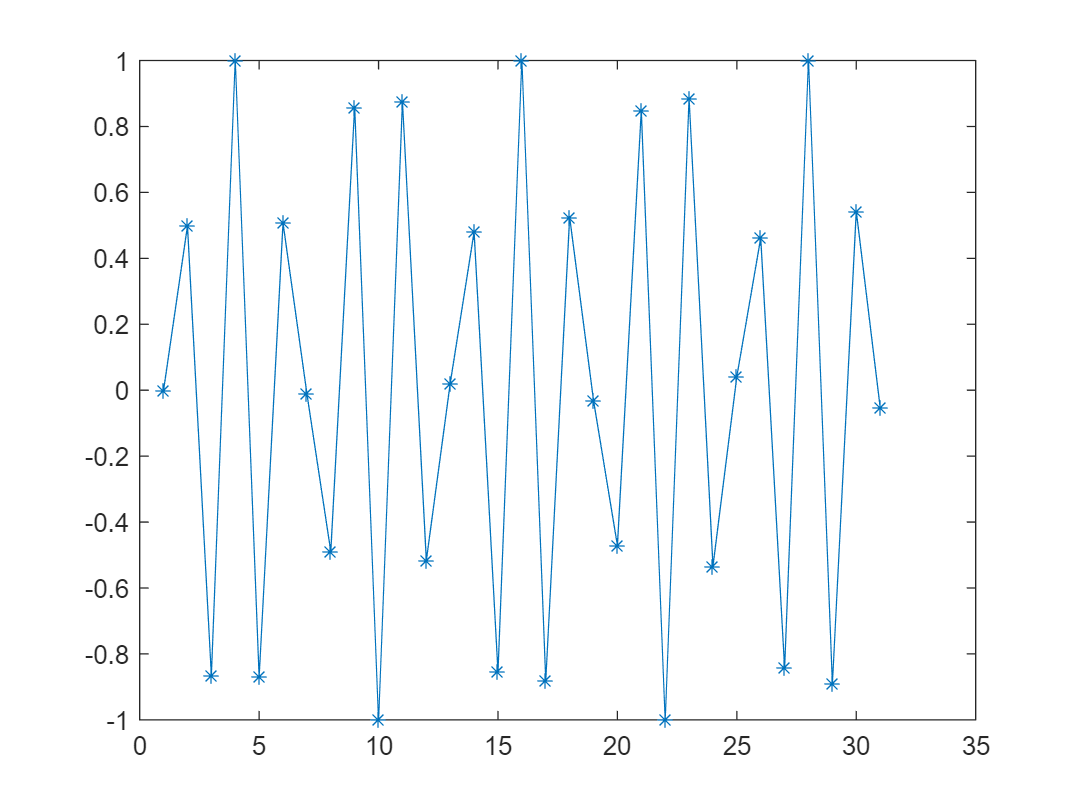

plot(imag(valuesOk),'-*');

А сигнал с разных направлений будет представлять, соответственно сумму разных гармонических сигналов.

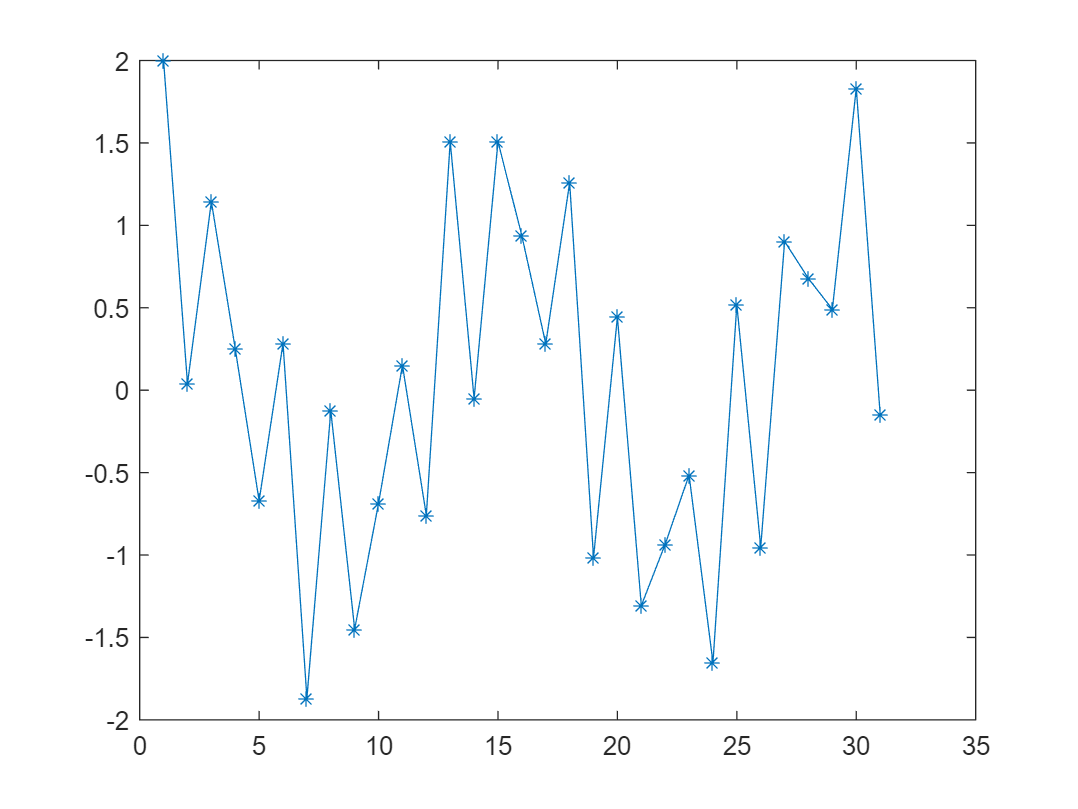

aimAngles = [56.5 8];
aimAmps   = [0 0]; %dB
valuesOk = distribution_former(dxOk,f,aimAngles, aimAmps);
plot(real(valuesOk),'-*');

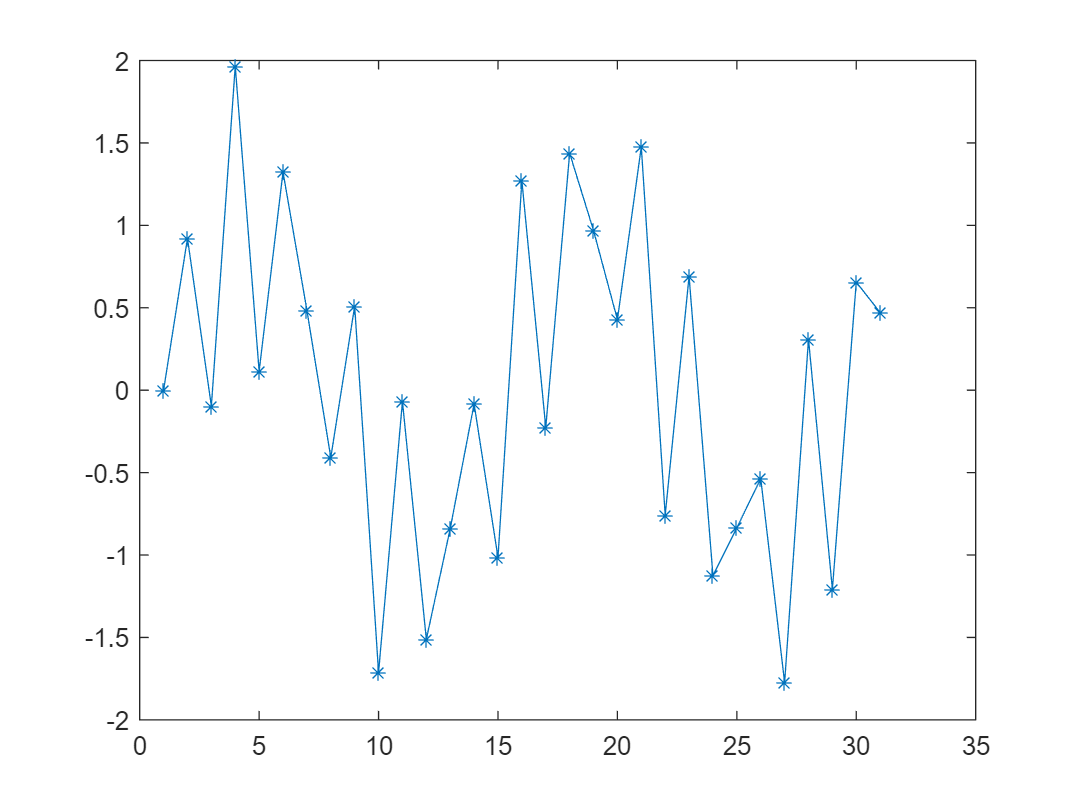

plot(imag(valuesOk),'-*');

если увеличить разрешение, это будет более заметно

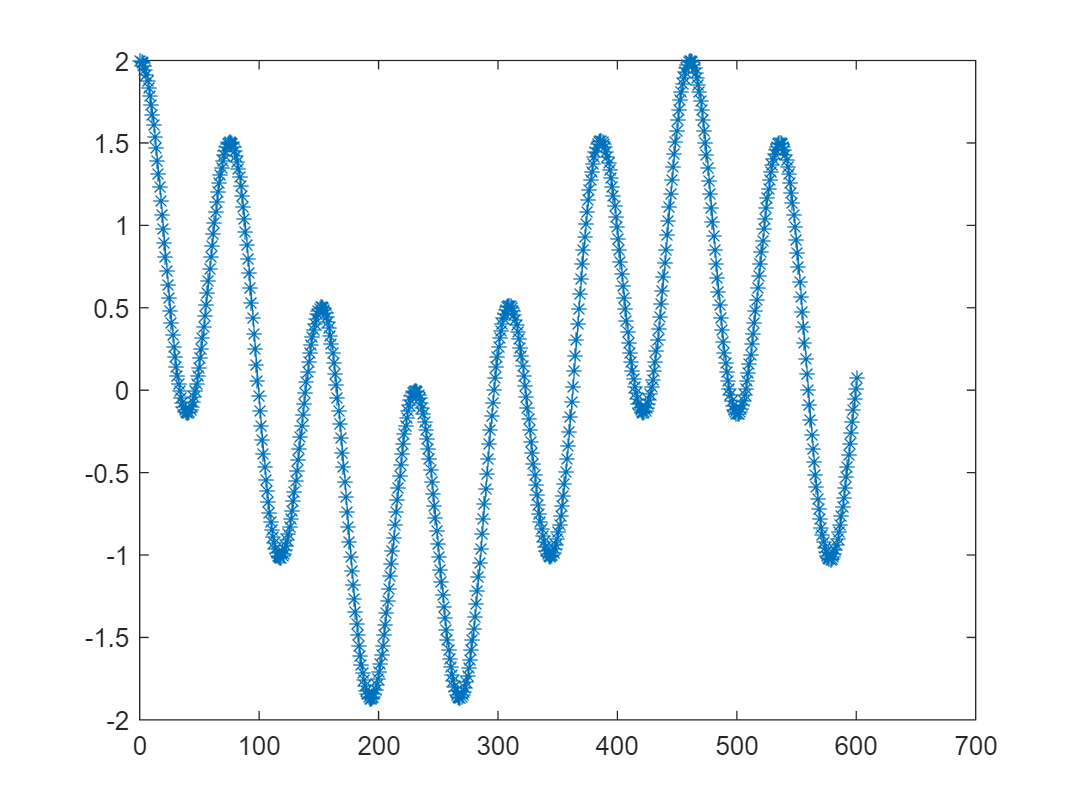

xmtmin = -0;xmtmax = 600;
dOk = lam/64;
NOk = round((xmtmax-xmtmin)/dOk);
dxOk = dOk*(xmtmin:1:xmtmax)';
aimAngles = [56.5 8];
aimAmps   = [0 0]; %dB
valuesOk = distribution_former(dxOk,f,aimAngles, aimAmps);
plot(real(valuesOk),'-*');

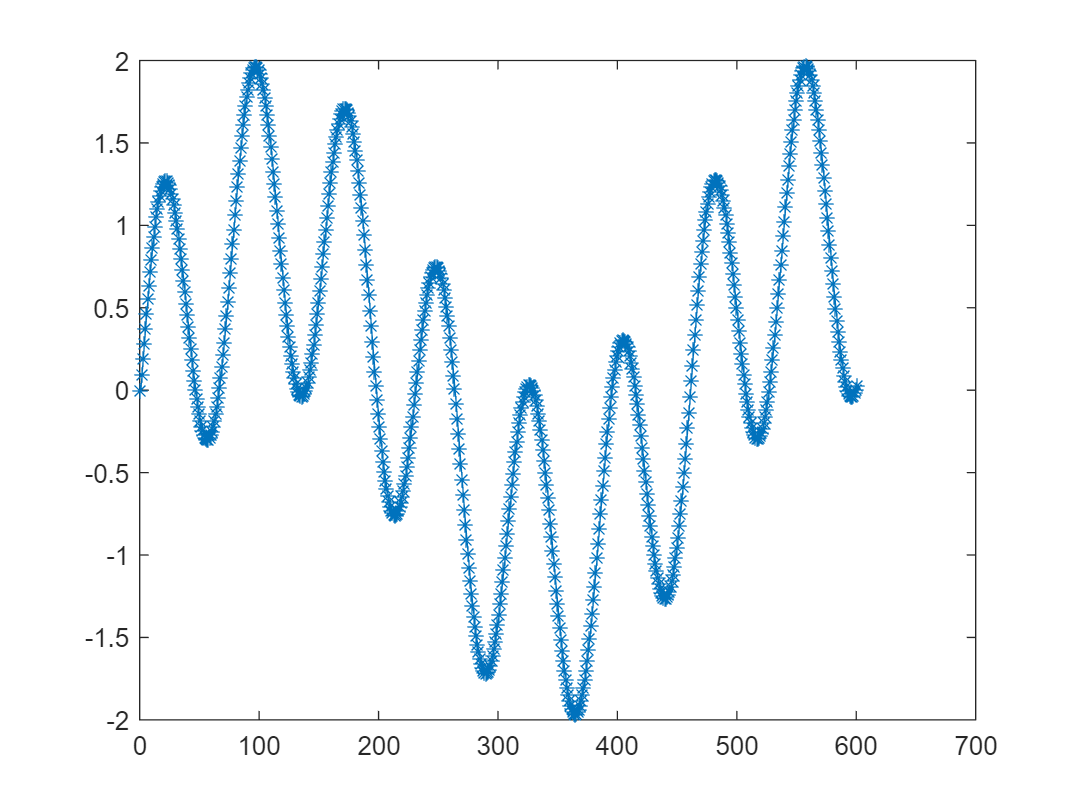

plot(imag(valuesOk),'-*');

Однако если множество $\{x\}$ будет выбрано слишком редко - информация о сигнале может быть потеряна

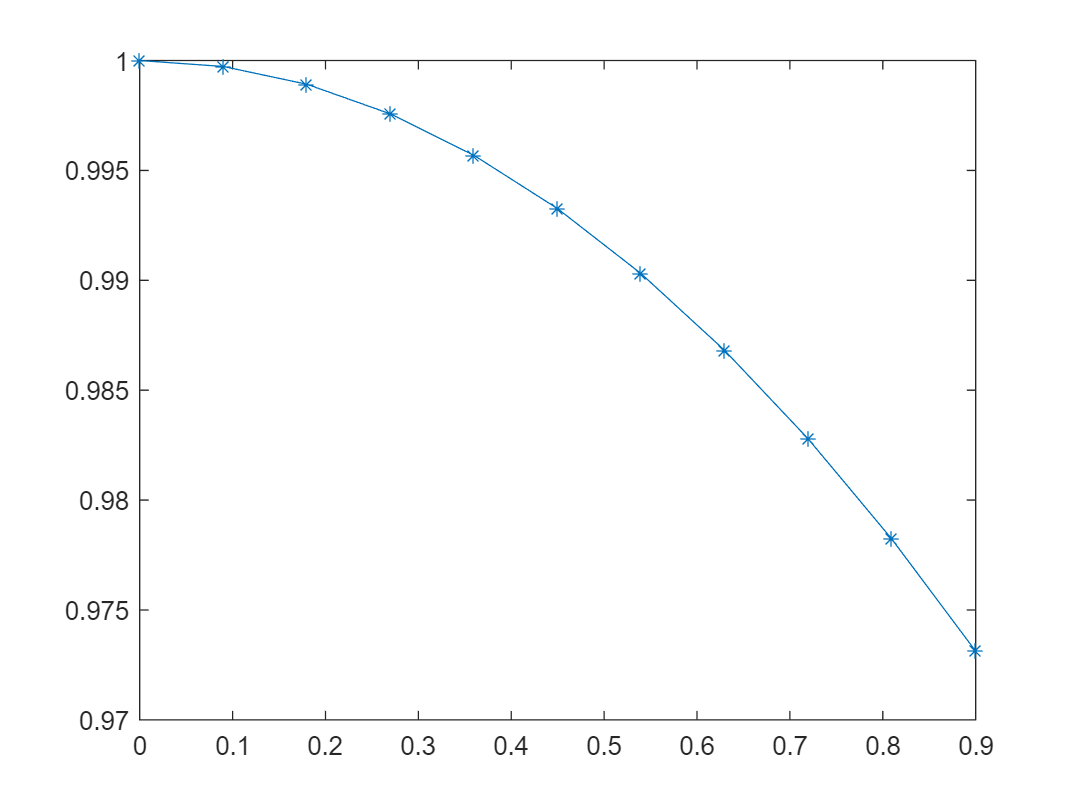

xmtmin = -0;xmtmax = 30;
dOk = lam/2;
NOk = round((xmtmax-xmtmin)/dOk);
dxOk = dOk*(xmtmin:1:xmtmax)';
aimAngles = [42];
aimAmps   = [0]; %dB
dxRare = dOk*(xmtmin:3:xmtmax)';
valuesRare = distribution_former(dxRare,f,aimAngles, aimAmps);
plot(dxRare,real(valuesRare),'-*');

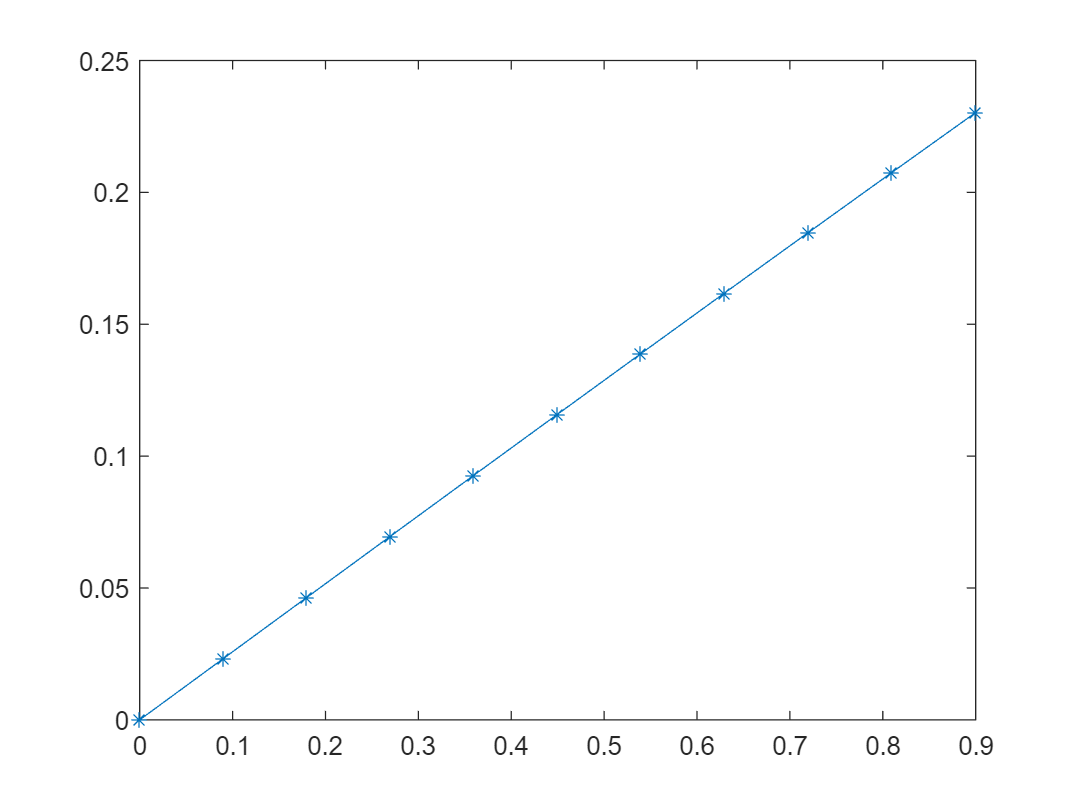

plot(dxRare,imag(valuesRare),'-*');

Тогда как должно быть

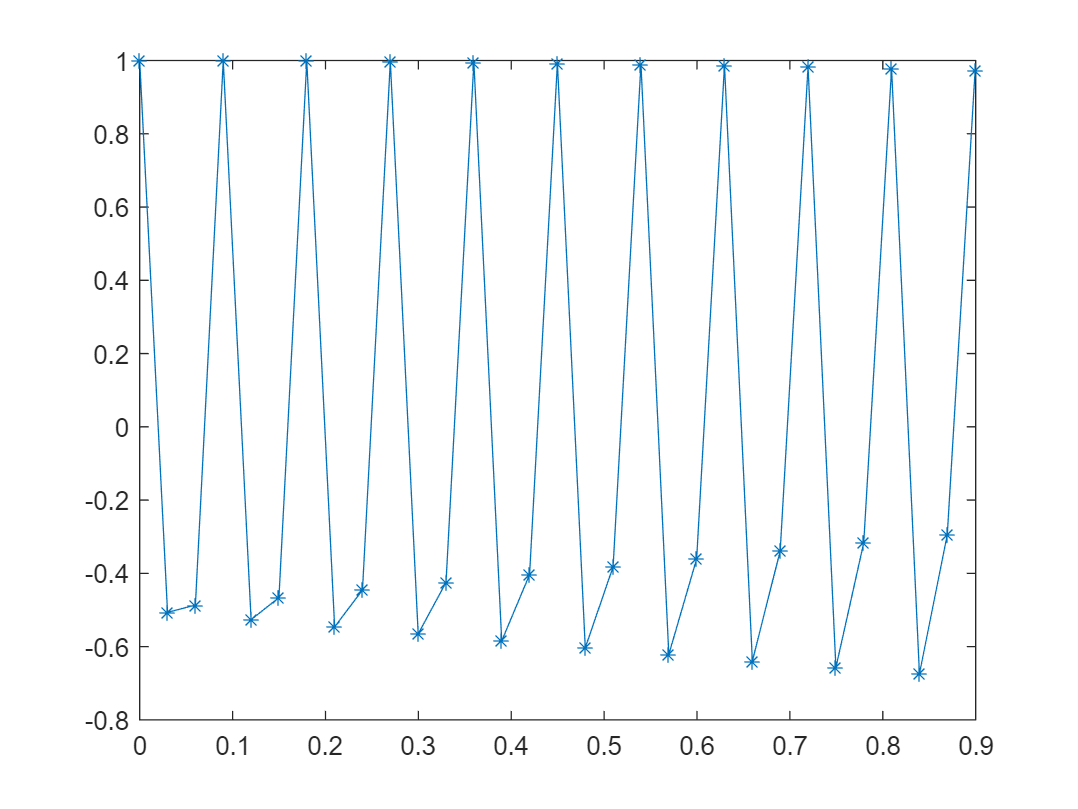

valuesOk = distribution_former(dxOk,f,aimAngles, aimAmps);
plot(dxOk,real(valuesOk),'-*');

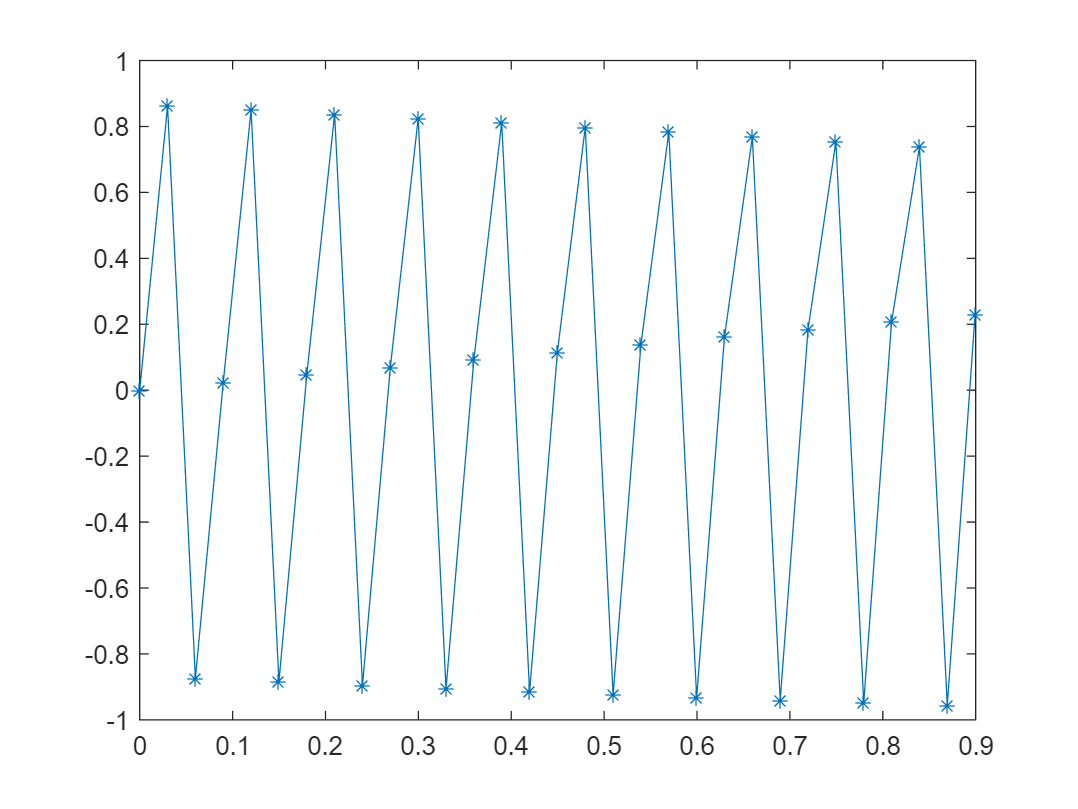

plot(dxOk,imag(valuesOk),'-*');

Однако если расположить точки неоднородно, можно извлечь информацию о сигнале из различных его частей

dxRare = 2*dOk*[-15 -14.75 -14.5 -7.25 -7 -6.75 -0.25 0 0.25 6.75 7 7.25 14.5 14.75 15];

Здесь выставлены 5 групп по 3 элемента, шаг между которыми составляет $\frac{\lambda}{4}$ 

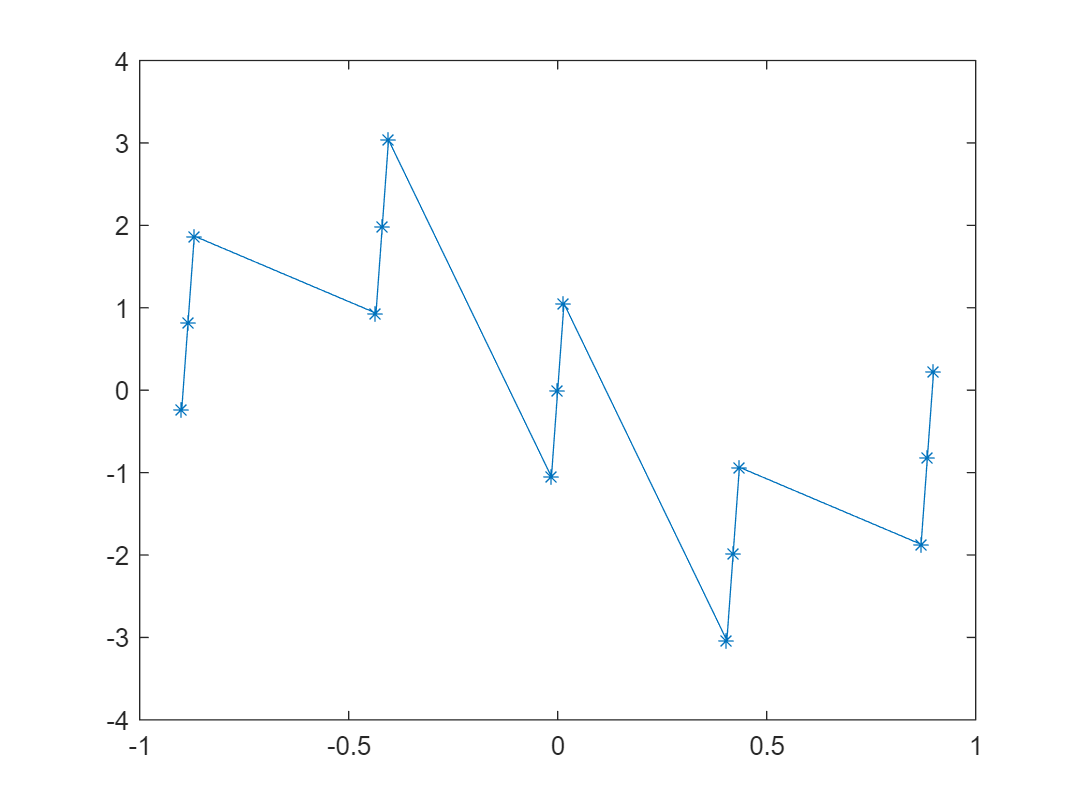

valuesRare = distribution_former(dxRare,f,aimAngles, aimAmps);
plot(dxRare,angle(valuesRare),'-*');

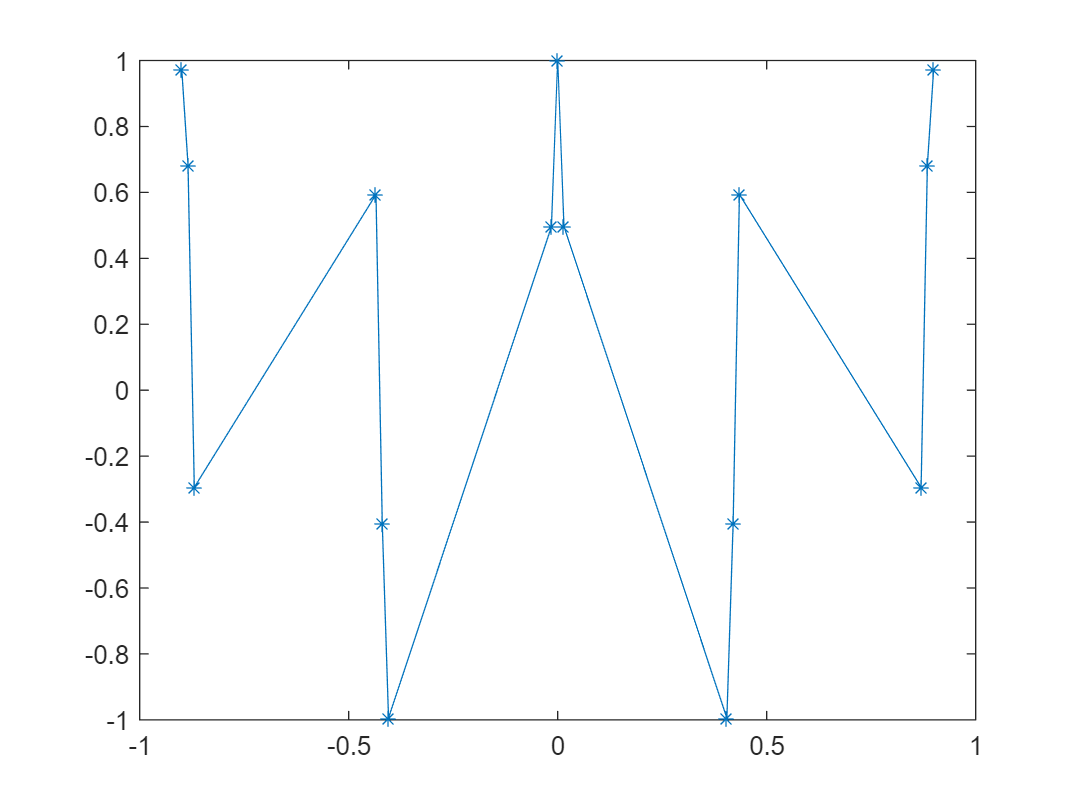

plot(dxRare,real(valuesRare),'-*');

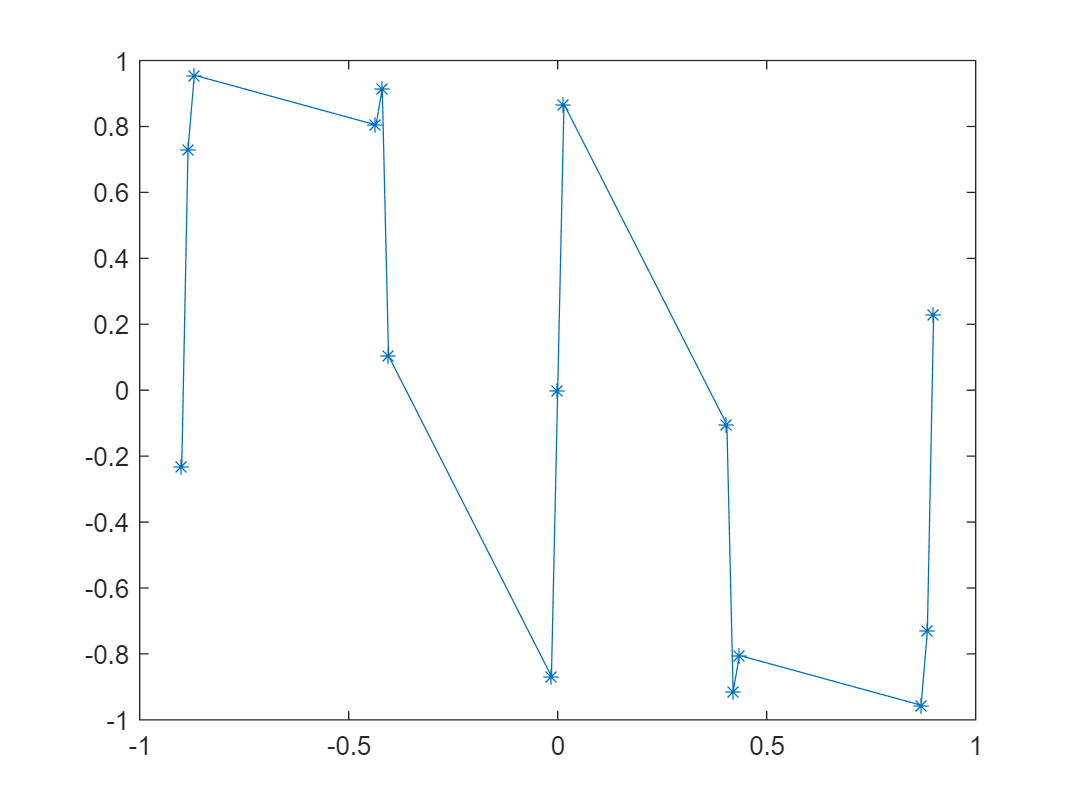

plot(dxRare,imag(valuesRare),'-*');

Если проводить интерполяцию комплексными синусоидами с условием обязательного прохождения через узлы интерполяции, можно попытаться восстановить действительный сигнал.